clear all
close all
F=5/2;
sigmax=spinOp(F,'x');
sigmay=spinOp(F,'y');
sigmaz=spinOp(F,'z');

s1=0;s2=0;s3=1;
theta=acos(s1)/2;
delta=acos(s2/sin(2*theta));

% phi=0;psi=pi/2;theta=pi/4;
% delta=phi-psi;

alpha_v=5;alpha_T=20/3;

vector=alpha_v*sin(2*theta)*sin(-delta)*sigmax/F/2;
tensor=alpha_T/(2*F*(2*F-1))*(6*(cos(theta))^2*sigmay^2+ ...
    6*(sin(theta))^2*sigmaz^2+ ...
    3*sin(2*theta)*cos(delta)*(1i*sigmax+2*sigmaz*sigmay));

ham=vector+tensor;
ham1=sigmax+sigmax^2;

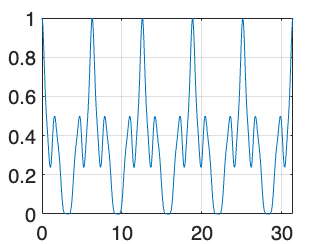

initial=[1 0 0 0 0 0]';
timelist=[0:0.01:10].*pi;
for i=1:length(timelist)
    time=timelist(i);
    final(:,i)=ham_evolve(ham,initial,time);    
end

figure;
plot(timelist,abs(final(1,:)).^2);
ylim([0 1])
grid on;

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end